# Luenberger Observer for the original Non-Linear System

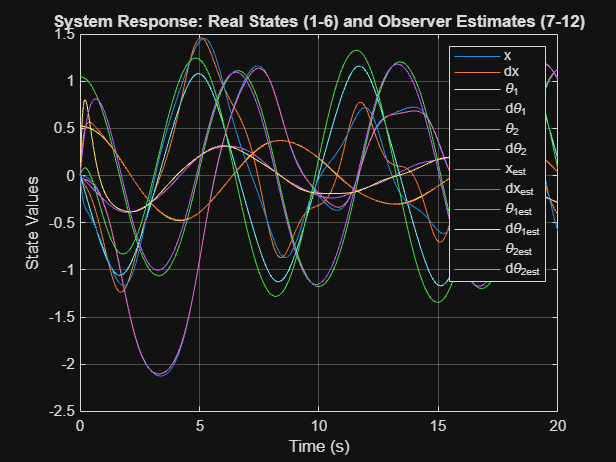

M = 1000; 
m1 = 100; 
m2 = 100; 
l1 = 20; 
l2 = 10; 
g = 9.81;

A = [0 1 0 0 0 0;
     0 0 -m1*g/M 0 -m2*g/M 0;
     0 0 0 1 0 0;
     0 0 -(M+m1)*g/(M*l1) 0 -m2*g/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 -m1*g/(M*l2) 0 -g*(M+m2)/(M*l2) 0];

B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

% Output Matrix (Case 4: Observable)
C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; % x(t), theta1(t) & theta2(t)


Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];

R = 0.1; 

K = lqr(A,B,Q,R);
poles = [-1; -2; -3; -4; -5; -6];
L = place(A', C4', poles)';

tspan = 0:0.01:20;
x0_plant = [0; 0; 30*pi/180; 0; 60*pi/180; 0]; 
x0_obs   = zeros(6,1);                         
y0 = [x0_plant; x0_obs];

[t, y] = ode45(@(t,y) observer_dynamics(t, y, M, m1, m2, l1, l2, g, A, B, C4, K, L), tspan, y0);


figure;
plot(t, y);
grid on;
title('System Response: Real States (1-6) and Observer Estimates (7-12)');
xlabel('Time (s)');
ylabel('State Values');
legend('x','dx','\theta_1','d\theta_1','\theta_2','d\theta_2', ...
       'x_{est}','dx_{est}','\theta_{1est}','d\theta_{1est}','\theta_{2est}','d\theta_{2est}');

## Function observer_dynamics

function dydt = observer_dynamics(~, y, M, m1, m2, l1, l2, g, A, B, C, K, L)
    x_real = y(1:6); x_est = y(7:12);
    u = -K * x_est; % Control using estimate
    
    
    th1 = x_real(3); dth1 = x_real(4); th2 = x_real(5); dth2 = x_real(6);
    denom = M + m1*sin(th1)^2 + m2*sin(th2)^2;
    numer = u - m1*l1*dth1^2*sin(th1) - m2*l2*dth2^2*sin(th2) ...
              - m1*g*cos(th1)*sin(th1) - m2*g*cos(th2)*sin(th2);
    x_dd = numer / denom;
    
    dx_real = [x_real(2); x_dd; x_real(4); (cos(th1)*x_dd - g*sin(th1))/l1; ...
               x_real(6); (cos(th2)*x_dd - g*sin(th2))/l2];
    
    
    dx_est = A*x_est + B*u + L*(C*x_real - C*x_est);
    
    dydt = [dx_real; dx_est];
end